proces u direktnoj grani (PT2)

K_pd = 20;
T_1 = 0.1;
T_2 = 0.005;

G_pd = tf(K_pd, [T_1*T_2 T_1+T_2 1])

G_pd =
 
             20
  ------------------------
  0.0005 s^2 + 0.105 s + 1
 
Continuous-time transfer function.



proces u povratnoj vezi (mjerni član, PT1)

K_pv = 0.1;
T_pv = 0.002;

G_pv = tf(K_pv, [T_pv 1])

G_pv =
 
      0.1
  -----------
  0.002 s + 1
 
Continuous-time transfer function.



PI regulator

K_Rs = 5; %K_Rs(simetrični optimum) = K_Rt(tehnički optimum)
T_It = T_1 %Tehnički optimum

T_It = 0.1000


G_R = tf(K_Rs*[T_It 1], [T_It 0])

G_R =
 
  0.5 s + 5
  ---------
    0.1 s
 
Continuous-time transfer function.




G_oRt = G_R*G_pd*G_pv %piši na papiru jer matlab ne krati zagrade

G_oRt =
 
                     s + 10
  --------------------------------------------
  1e-07 s^4 + 7.1e-05 s^3 + 0.0107 s^2 + 0.1 s
 
Continuous-time transfer function.



K_oRt = (K_Rs*K_pd*K_pv)/T_It

K_oRt = 100

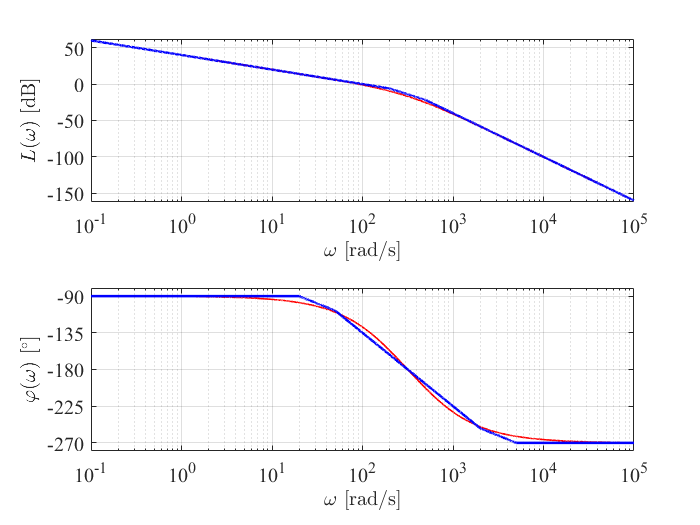

wca = 100.0691

wpia = 316.3370

AOa = 13.9854

FOa = 44.9730


[wca,wpia,AOa,FOa]=Bode_IDT3(K_oRt,T_It,T_1,T_2,T_pv)

PI regulator

K_R = 5;
T_Is = 0.05; %simetrični optimum
G_R = tf(K_R*[T_Is 1], [T_Is 0])

G_R =
 
  0.25 s + 5
  ----------
    0.05 s
 
Continuous-time transfer function.




K_oRts = (K_R*K_pd*K_pv)/T_Is

K_oRts = 200

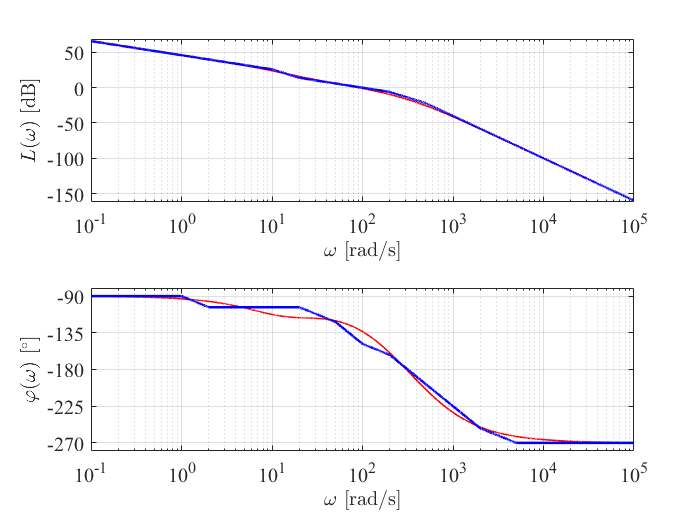

wca = 100.0691

wpia = 316.3370

AOa = 13.9854

FOa = 31.4401


[wca,wpia,AOa,FOa]=Bode_IDT3(K_oRts,T_Is,T_1,T_2,T_pv)

K_i = 20;
T_1i = 0.001;